# The example of Find_NRPS_motif_module_pfam_HRL

This script shows how to use this function

1. Assgin all parameters

2. Minimal parameters without seting Pfam_database_path and reference_motif_path in the function

3. Minimal parameters with seting Pfam_database_path and reference_motif_path in the function

## 0. load data

toolboxpath='D:/Shared with me/MATLAB_toolbox';
if exist(toolboxpath,'dir')
    addpath(toolboxpath)
else
    error('Wrong path for MATLAB additional toolbox, please check\n')
end
seq=fastaread('test.fasta');

## 1. Assgin all parameters

If you want to change default value, you need to assgin parameters.

Pfam_database_path='D:/cygwin64/home/74005/Pfam';
reference_motif_path='D:/Shared with me/MATLAB_toolbox/reference_motif';
new_motif={'Aalpha','G','Talpha'};
loop_S_code_judge=1;
length_threshold=0.6;
length_threshold_TE=0.5;
result1 = Find_NRPS_motif_module_pfam_HRL(seq,Pfam_database_path,reference_motif_path,new_motif,loop_S_code_judge,length_threshold,length_threshold_TE);

## 2.Minimal parameters without seting Pfam_database_path and reference_motif_path in the function

If you are not familar with Matlab or this function, you can only set minimal parameters.

Pfam_database_path='D:/cygwin64/home/74005/Pfam';
reference_motif_path='D:/Shared with me/MATLAB_toolbox/reference_motif';
% new_motif={'Aalpha','G','Talpha'};
% loop_S_code_judge=1;
% length_threshold=0.6;
% length_threshold_TE=0.5;
result2 = Find_NRPS_motif_module_pfam_HRL(seq,Pfam_database_path,reference_motif_path);

## 3.Minimal parameters with seting Pfam_database_path and reference_motif_path in the function

User can set Pfam_database_path and reference_motif_path in the function file Find_NRPS_motif_module_pfam_HRL.m

Change Pfam_database_path and reference_motif_path into your path.

It's convenient and user only need input seq. 

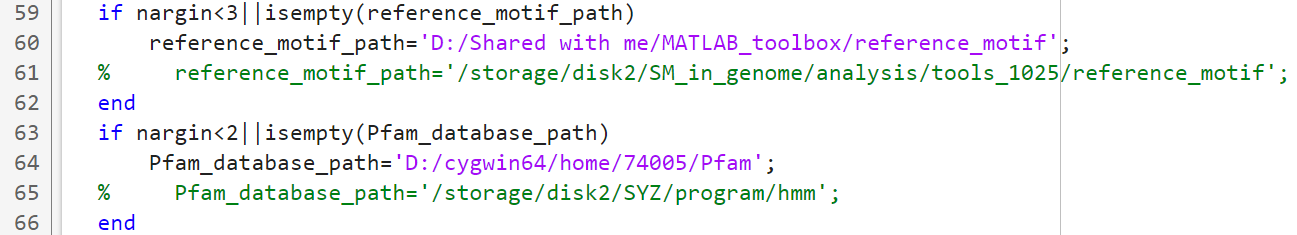

result3 = Find_NRPS_motif_module_pfam_HRL(seq);

## 4.Output

We take result1 as example:

The input sequences are 3 NRPS with known structure (PDB ID: 2VSQ, 4ZXI, 6LTA)